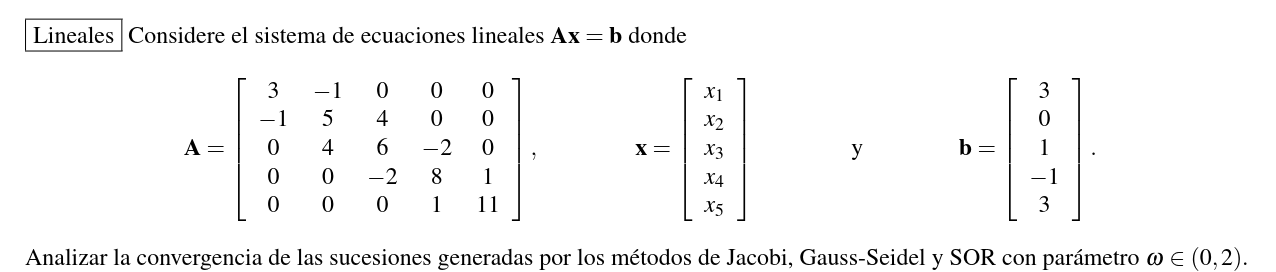

clear 
syms x [1,5]
A = [3 -1 0 0 0;-1 5 4 0 0;0 4 6 -2 0; 0 0 -2 8 1;0 0 0 1 11]

A =      3    -1     0     0     0
    -1     5     4     0     0
     0     4     6    -2     0
     0     0    -2     8     1
     0     0     0     1    11


b = transpose([3 0 1 -1 3])

b =      3
     0
     1
    -1
     3



eig(A)

ans =     0.9435
    3.1612
    7.1747
   10.2484
   11.4721


D = diag(diag(A));
L = tril(A) - D;
U = triu(A) - D;

## Ahora hallemos el w optimo a partir de del readio de la matriz de jacobi

Tj = inv(D)*(L+U);

RadioJ = max(abs(eig(Tj)));

w = 2/(1+ sqrt(1- RadioJ^2))

w = 1.2748

### Ahora hagamos una aproximacion sor con x(0)

x0 = transpose([1 2 3 4 5]);

Y = sor (A,b, x0, w, 1e-8, 200)

k = 20

Y =     1.0962
    0.2886
   -0.0866
   -0.1828
    0.2893


R = A*Y - b

R = 1.0e-08 *

   -0.3006
   -0.5252
   -0.2897
   -0.0482
    0.0378


norm(R,1)

ans = 1.2014e-08

### Ahora probemos con jacobi y gauss-seidel

X = jacobi (A, b, x0, 1e-8, 200);

k = 101

err = 1.1093e-08

z = gseid (A, b, x0, 1e-8, 200);

k = 50



residuoJ = A*X - b

residuoJ = 1.0e-07 *

    0.0677
   -0.3482
   -0.3097
    0.1596
    0.0194


norm(residuoJ,1)

ans = 9.0466e-08

residuoGS = A*z - b

residuoGS = 1.0e-07 *

   -0.0778
   -0.2371
    0.0301
    0.0014
         0


norm(residuoGS,1)

ans = 3.4636e-08

#### Finalmente, veamos que se cumple lo que dice el teorema ρ(T gs) = [ρ(T j)]2 y ρ(Tωopt ) =ωopt − 1

Tgs=inv(D-L)*U

Tgs =          0   -0.3333         0         0         0
         0    0.0667    0.8000         0         0
         0    0.0444    0.5333   -0.3333         0
         0   -0.0111   -0.1333    0.0833    0.1250
         0   -0.0010   -0.0121    0.0076    0.0114


radioTgs=max(abs(eig(Tgs)))

radioTgs = 0.6764

Tw=inv(D-w*L)*((1-w)*D+w*U)

Tw =    -0.2748   -0.4249         0         0         0
    0.0701   -0.1665    1.0199         0         0
    0.0595   -0.1415    0.5919   -0.4249         0
   -0.0190    0.0451   -0.1887   -0.1394    0.1594
   -0.0022    0.0052   -0.0219   -0.0162   -0.2563


radioTw=max(abs(eig(Tw)))

radioTw = 0.2748